# Analysing visual coding electrophysiology data from the Allen Brain Observatory, with the Brain Observatory Toolbox

The Allen Brain Observatory resource [1] comprises datasets of neural activity obtained from the mouse visual cortex collected during visual stimulus presentation. The Visual Coding – Neuropixels dataset [[2](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels)] consists of neural activity recordings obtained using multi-channel electrophysiology.

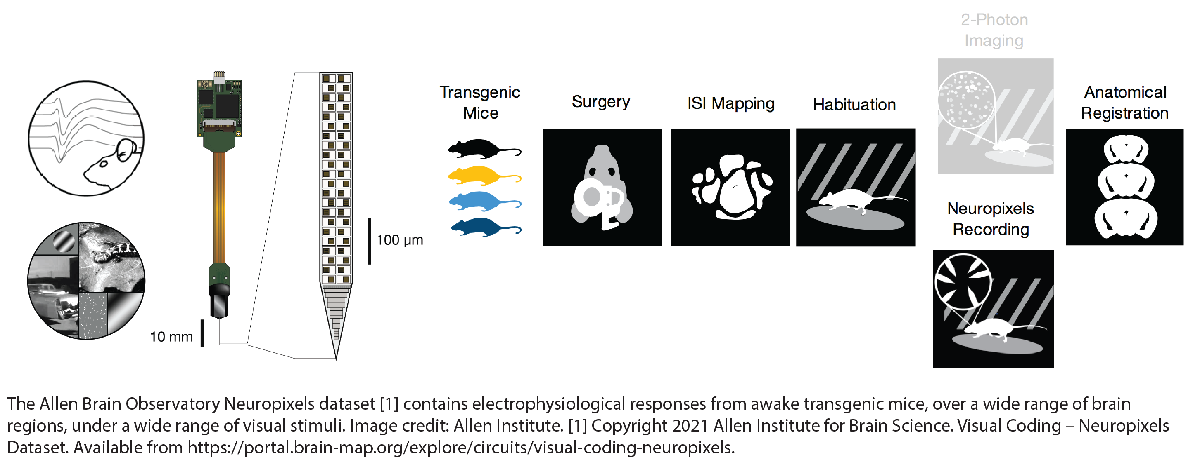

This example demonstrates how to access, search, and filter data from the Visual Coding – Neuropixels dataset using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT). It also shows how to perform some simple analyses of visual responses by neurons in mouse primary visual cortex. Neural response properties such as receptive field and orientation tuning are quantified, along with basic behavioural analysis.

The electrophysiology data for individual experimental sessions can be large — in the order of several GBytes for each experimental session. Be aware that running this demo will cause the download of approximately 5GB of data, which may take considerable time. This data will be cached by the toolbox, so that subsequent runs of the demo will be fast.

## About the Brain Observatory Toolbox (BOT)

The BOT is a MATLAB toolbox for accessing, manipulating and analysing neurophysiology data from the Allen Brain Observatory. The BOT provides convenient methods for identifying data sets of interest, and manages downloading and caching of data from the Allen Brain Observatory.

## The Neuropixels data

The Neuropixels dataset contains extracellular electrophysiology data obtained using high-denisty Neuropixels probes placed in different regions of the mouse brain (for a complete listing see the technical white paper on the Allen Institute's Mouse Common Co-ordinate Framework [[3](http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2)]). Neural activity from cortex and thalamus was recorded during passive visual stimulation. Further details regarding stimuli can be found in the Allen Institute's SDK documentation [[4](https://allensdk.readthedocs.io/en/latest/visual_coding_neuropixels.html#visual-stimulus-sets)] and the Neuropixels dataset technical white paper [[5](https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf)]. Briefly, stimuli were chosen from a stimulus set known as the 'Brain Observatory 1.1'. Stimuli included Gabor patches, full field flashes, drifting and static gratings with different orientations and natural scenes and movies while the subject ran on a wheel. 

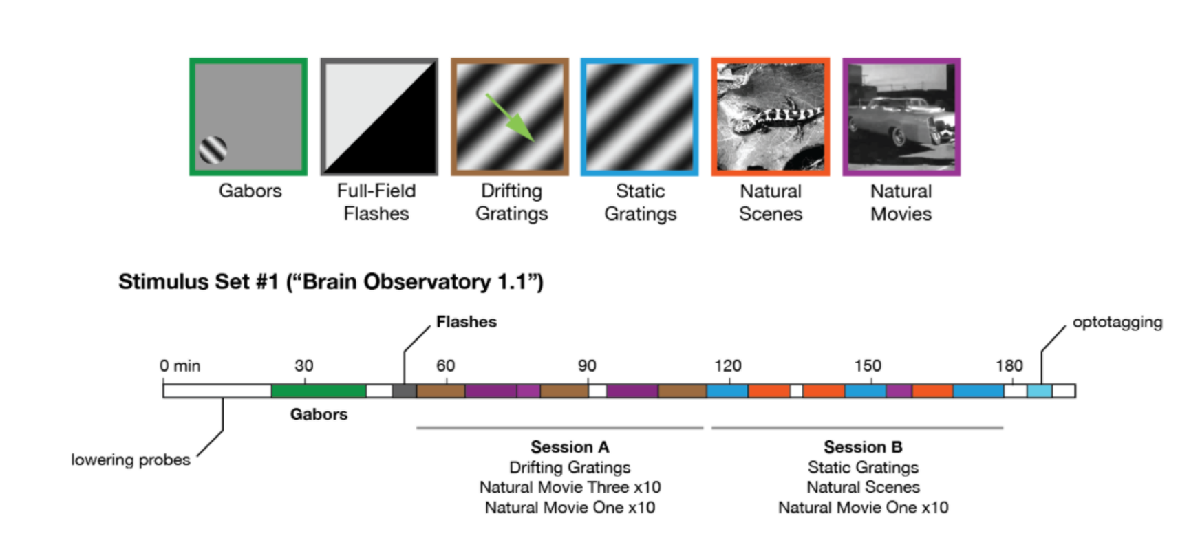

*Fig: Stimulus sets used in the Brain Observatory. Image Credit: Allen Brain Observatory*

The data was pre-processed using [standard procedures](https://allensdk.readthedocs.io/en/latest/visual_coding_neuropixels.html#data-processing) and saved using [Neurodata Without Borders (NWB)](https://www.nwb.org/) file formats. Neural activity from each channel was saved in two streams 

- A high pass (analog 500 Hz and digital 150 Hz) filtered 'spike band' digitized at 30 kHz (Spikes were sorted using the MATLAB package Kilosort2 and quality metrics computed)

- A low pass (analog 1kHz and digital 625 Hz) filterted 'LFP band' digitized at 2.5 kHz and re-referenced for common noise rejection.

The data is described by several tables containing metadata whereas the actual data is stored in NWB files. Running this demo requires a total of 5GB of data to be downloaded which might take some time the first time. However, the data is then cached by this toolbox making subsequent runs faster. Metadata stored in tables is used to pre-select the data required for an analyses following which, only the minimum required actual data from NWB files is accessed. 

## Obtaining and examining experimental data 

The Neuropixels data is grouped and organized by several ***linked dataset items*** of different types - experimental `sessions`, containing data from several `probes` which, in turn, contain data from multiple `channels` and `units`. Each dataset item type can be accessed using the `bot.fetch``LinkedDatasetItemType``()` functions. Information regarding all dataset items of a particular type with item parameters such as unique identifiers (`id`) are available as tables. An individual dataset item can be queried from the table (using the row) or as an object (using the item id). Objects come with properties used to inspect information related to that particular dataset item or methods for fetching or analyzing data linked to that particular dataset item.

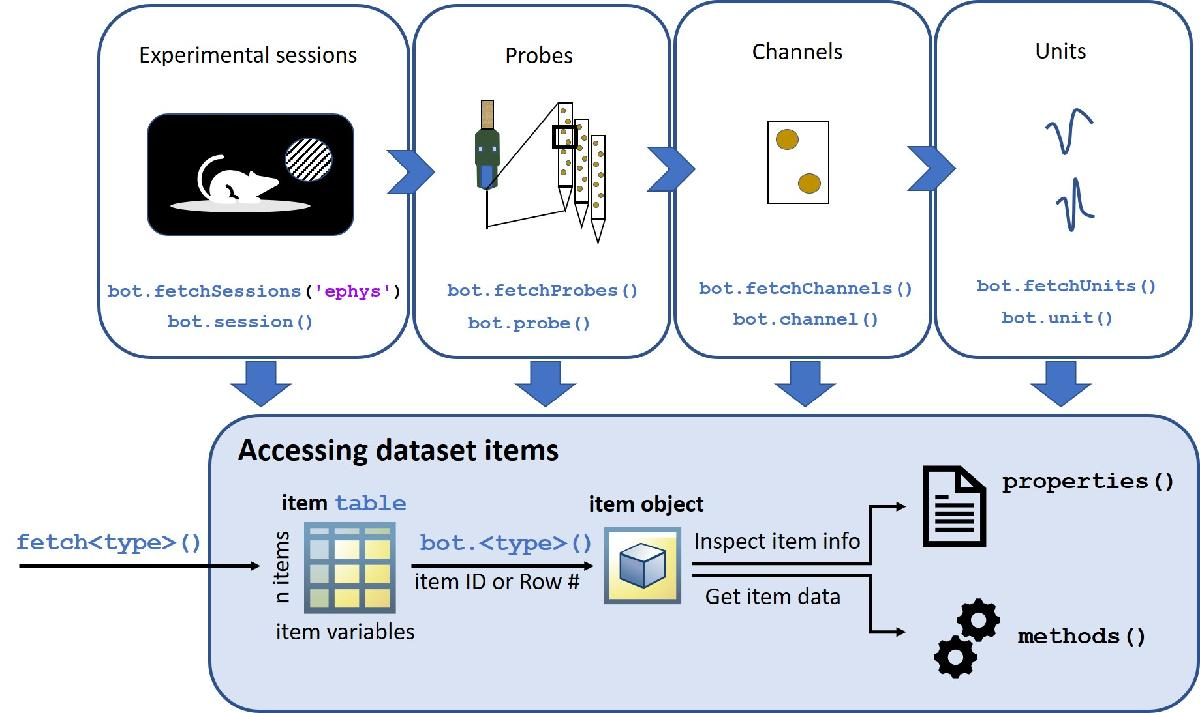

*Fig: Schematic showing relationship of the different *`LinkedDatasetItem`*s to each other and *`bot.fetch`* functions for accessing each.*

% prepare for demo
prepareForDemo;

We are going to start by accessing all the sessions in this dataset using the `bot.fetchSessions ('ephys')` factory function. To access probes, channels or units instead of sessions, use `bot.fetchProbes`, `bot.fetchChannels` and `bot.fetchUnits` respectively

% - Obtain sessions, probes, channels and units tables
sessions = bot.fetchSessions('ephys'); % for accessing probes, channels, session

Fetching EPhys sessions manifest...
Fetching EPhys units manifest...
Fetching.... [4%]
Fetching.... [7%]
Fetching.... [11%]
Fetching.... [15%]
Fetching.... [18%]
Fetching.... [22%]
Fetching.... [26%]
Fetching.... [30%]
Fetching.... [33%]
Fetching.... [37%]
Fetching.... [41%]
Fetching.... [44%]
Fetching.... [48%]
Fetching.... [52%]
Fetching.... [55%]
Fetching.... [59%]
Fetching.... [63%]
Fetching.... [67%]
Fetching.... [70%]
Fetching.... [74%]
Fetching.... [78%]
Fetching.... [81%]
Fetching.... [85%]
Fetching.... [89%]
Fetching.... [92%]
Fetching.... [96%]
Fetching.... [100%]
Fetching EPhys channels manifest...
Fetching.... [4%]
Fetching.... [8%]
Fetching.... [12%]
Fetching.... [16%]
Fetching.... [20%]
Fetching.... [24%]
Fetching.... [28%]
Fetching.... [32%]
Fetching.... [37%]
Fetching.... [41%]
Fetching.... [45%]
Fetching.... [49%]
Fetching.... [53%]
Fetching.... [57%]
Fetching.... [61%]
Fetching.... [65%]
Fetching.... [69%]
Fetching.... [73%]
Fetching.... [77%]
Fetching.... [81%]
Fetch

Session information is returned as a table. Columns correspond to session parameters

% - Display the sessions manifest
head(sessions)

ans = 8×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                      ephys_structure_acronyms                                                    isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _________________________________________________

You can use these tables to locate sessions or individual recordings that meet your criteria, for example, those using wild type animals that included eye tracking data.

% - Select sessions that include valid eye tracking data
sessions = sessions(~sessions.fail_eye_tracking, :);

% - Select sessions on wild-type animals
sessions = sessions(sessions.full_genotype == "wt/wt", :)

sessions = 26×15 table
       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                                      ephys_structure_acronyms                                                      isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    ________________________________________

## Obtaining and examining a single experimental session

Let's choose the first of the remaining experimental sessions in the `sessions` table, and examine it in more detail. In the BOT, all experimental data are represented by summaries, with loading of large nwb data files (slow) performed only when necessary.

A single experimental session is obtained using the `bot.session()` factory function:

% - Obtain a single experimental session
sess = bot.session(sessions(1, :))

sess =   ephyssession with properties:

                              info: [1×1 struct]
                                id: 742951821
                       nwbIsCached: 1
                      nwbLocalFile: "C:\Users\vijayi\MATLAB\PROJECTS\Brain-Observatory-Toolbox\+bot\Cache\external\neuralcoding\prod56\specimen_723627604\ecephys_session_742951821\EcephysWriteNwbStrategy\analysis_run_1026121965\ecephys_session_742951821.nwb"

   Item Info Values
                structure_acronyms: [7×1 string]

   Linked Items
                            probes: [6×23 table]
                          channels: [2219×29 table]
                             units: [893×51 table]

   Linked Item Values
       channel_structure_intervals: [18×2 table]
         structurewise_unit_counts: [7×2 table]

   NWB Info
                    mean_waveforms: '[on demand]'
                  spike_amplitudes: '[on demand]'
                  

The `session` object collects a number of useful metadata properties (including detailed metadata in `.metadata`); a set of tables summarizing the linked dataset items contained by this session; and a number of properties relating to the NWB data, indicating whether or not that particular data is already downloaded into the BOT cache.

For the NWB data properties, `'[cached]'` indicates that the NWB data has previously been downloaded from the Allen Brain Observatory; `'[not cached]'` indicates that data is not yet downloaded. Accessing one of these properties will cause data to be loaded from the cache, or downloaded if necessary. Many of these data files can be several GB in size and downloading them for the first time might be slow.

Let's look at the metadata for this session:

sess.info

ans = struct with fields:
                          id: 742951821
                  unit_count: 893
               channel_count: 2219
                 probe_count: 6
                session_type: brain_observatory_1.1
                 age_in_days: 120
           fail_eye_tracking: 0
                         sex: M
               full_genotype: "wt/wt"
    ephys_structure_acronyms: "VIS; VISal; VISl; VISp; VISpm; VISrl; grey"
           isi_experiment_id: 732238627
         date_of_acquisition: 26-Oct-2018 19:47:04
                 specimen_id: 723627604
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]


### Querying important parameters regarding a particular session

We can see some important information about this recording session. For example,

- What kind of animal was the data recorded from?

"The experimental subject was of " + char(sess.info.sex) + " sex and " + sess.info.full_genotype + "genotype"

ans = "The experimental subject was of M sex and wt/wtgenotype"

- How many linked dataset items (probes, channels & units) are included in this session?

"This recording had " + sess.info.probe_count + " probes, " + sess.info.channel_count + " channels and " + sess.info.unit_count + " units"

ans = "This recording had 6 probes, 2219 channels and 893 units"

We can examine the session further to see the brain regions from which these units were recorded. 

sess.structurewise_unit_counts

ans = 7×2 table
    ephys_structure_acronym    count
    _______________________    _____

             grey               554 
             VIS                108 
             VISrl               79 
             VISl                52 
             VISal               44 
             VISp                33 
             VISpm               23 


The brain region acronyms follow the Allen Brain Institute's Mouse Common Co-ordinate Framework (CCF version 3) and are explained in detail [here](http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2). The brain region acronyms will be linked to all linked dataset items and can be used at any stage to extract brain region wise parameters of the data. For example, let us look at the distribution of firing rates across the different brain regions recorded in this dataset.

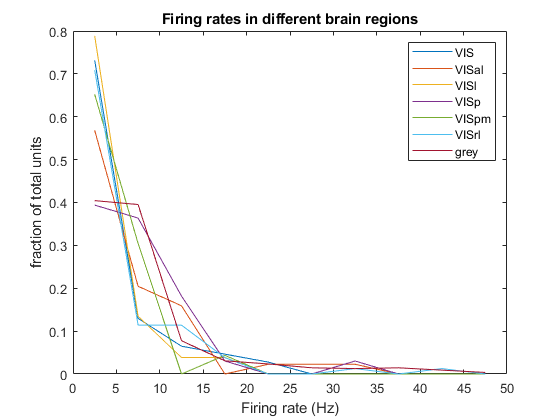

units = sess.units;
UnitsByBrainRegion = cellfun(@(x)(units(units.ephys_structure_acronym==x,:)),sess.structure_acronyms,'UniformOutput',0); % find units matching each of the brain regions studied in this session
firingRatesByBrainRegion = cellfun(@(x)(x.firing_rate),UnitsByBrainRegion,'UniformOutput',0); % get firing rates of all units by brain region
n = cellfun(@(x)(histcounts(x,0:5:50,'Normalization','probability')),firingRatesByBrainRegion,'UniformOutput',0); % plot
plot(2.5:5:50,cell2mat(n))
legend(brainRegionsRecorded)
title('Firing rates in different brain regions')
xlabel('Firing rate (Hz)')
ylabel('fraction of total units')

One can see that the distribution of firing rates across the different visual cortical areas is, unsurprisingly, similar

## Accessing the data linked to a particular experimental session

Now that we have had an overview of the data within an experimental session, let us retrieve the actual data for some analyses

### Visualise pupil location during the experiment

Let us start off by retrieving the pupil tracking via the method `.fetch_pupil_data()` to visualise the pupil location as a location density map.

% Get the table of pupil locations
pupil_loc = sess.pupil_data

pupil_loc = 288131×16 table
    timestamps    corneal_reflection_center_x    corneal_reflection_center_y    corneal_reflection_height    corneal_reflection_width    corneal_reflection_phi    pupil_center_x    pupil_center_y    pupil_height    pupil_width    pupil_phi    eye_center_x    eye_center_y    eye_height    eye_width    eye_phi 
    __________    ___________________________    ___________________________    _________________________    ________________________    ______________________    ______________    ______________    ____________    ___________</

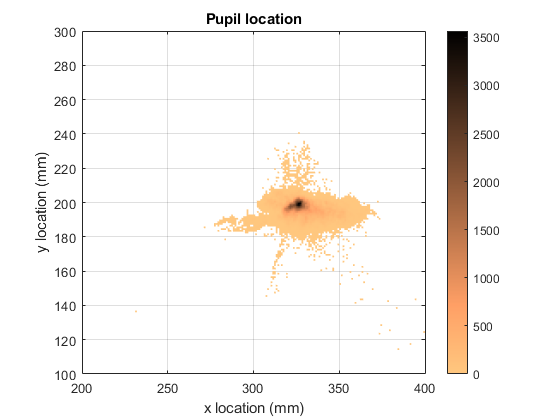

% Plot a 2D histogram of pupil location
histogram2(pupil_loc.pupil_center_x, pupil_loc.pupil_center_y, 'DisplayStyle', 'tile');
xlim([200 400]);
ylim([100 300]);
cmap = copper();
colormap(cmap(end:-1:1, :));
axis square;
xlabel('x location (mm)');
ylabel('y location (mm)');
title('Pupil location');
colorbar

### Examining the stimuli used in this experiment

The properties `.stimulus_names`, `.stimulus_conditions`, `.stimulus_presentations` etc. contain information about what stimuli were presented in this session, and details about the stimulus parameters and in what order the stimuli were presented.

% Show which stimuli were presented in this session
sess.stimulus_names

ans = 8×1 string array
    "drifting_gratings"
    "flashes"
    "gabors"
    "natural_movie_one"
    "natural_movie_three"
    "natural_scenes"
    "spontaneous"
    "static_gratings"


% Get a table with detailed parameters for each stimulus
head(sess.stimulus_conditions)

ans = 8×17 table
    contrast      mask       opacity    orientation                 phase                       size         spatial_frequency    stimulus_name    temporal_frequency      units      stimulus_block_condition_id    frame    x_position    y_position      color_triplet      color    stimulus_condition_id
    ________    _________    _______    ___________    ________________________________    ______________    _________________    _____________    __________________    _________    ___________________________

% Get a full table of inidividual stimulus presentations
stimuli = sess.stimulus_presentations;
head(stimuli)

ans = 8×19 table
    contrast    stimulus_block_id    orientation                 phase                       size         spatial_frequency    start_time    stimulus_block    stimulus_name    stop_time    temporal_frequency    stimulus_block_condition_id    frame    x_position    y_position    stimulus_presentation_id    color    duration    stimulus_condition_id
    ________    _________________    ___________    ________________________________    ______________    _________________    __________    ______________    _______

### Stimulus conditions and stimulus presentations

The stimuli in a session are identified using two different properties

- `stimulus_conditions`

- `stimulus_presentations`

As the name implies, these two classify each stimulus according to two different criteria. Each `stimulus_condition` contains identical stimuli defined by a set of parameters. Over the course of one experimental session, a stimulus condition can be repeated several times and two stimuli can have different several `stimulus_presentation_ids` but the same `stimulus_condition_id `whereas, `stimulus_presentations` are unique to each stimulus .  

For example, the 6th and 11th stimulus presentations have different s`timulus_presentation_ids(5,10)` but the same `stimulus_condition_id` of 5 (Gabor patches at a position of [10,30] mm with a orientation of 45 degrees). 

selectedVars = matches(stimuli.Properties.VariableNames,...
    {'stimulus_presentation_id',...
    'stimulus_condition_id',...
    'stimulus_name',...
    'x_position',...
    'y_position',...
    'orientation'});
stimuli([6,11],selectedVars)

ans = 2×6 table
    orientation    stimulus_name    x_position    y_position    stimulus_presentation_id    stimulus_condition_id
    ___________    _____________    __________    __________    ________________________    _____________________

        45           "gabors"           10            30                    5                         5          
        45           "gabors"           10            30                   10                         5          


The method .`conditionwise_spike_statistics()` computes spike statistics by stimulus condition whereas the method .`presentationwise_spike_counts()` returns spike counts for different stimulus presentations.

### Examining details of an individual stimulus presentation (Gabor patches)

One of the stimuli used were Gabor patches of different orientations that were distributed across the visual field in a grid like manner. Let us extract the Gabor patch stimulus sets (`gabors`) used in this session and examine details of stimulus presentation.

% extract Gabor patches from stimulus set
GaborPatchIndices = stimuli(stimuli.stimulus_name=='gabors', :);
% extract stimulus locations and orientations
StimXloc = unique(GaborPatchIndices.x_position);
StimYloc = unique(GaborPatchIndices.y_position);
StimOrnt = unique(GaborPatchIndices.orientation);
% display stimulus properties
['stimulus x pos: ',num2str(StimXloc'),newline,...
    'stimulus y pos: ',num2str(StimYloc'),newline,...
    'stimulus orientation: ',num2str(StimOrnt')]

ans =     'stimulus x pos: -40 -30 -20 -10   0  10  20  30  40
     stimulus y pos: -40 -30 -20 -10   0  10  20  30  40
     stimulus orientation: 0  45  90'


## Examining data from a single unit

Let's access the first recoded unit in this session from primary visual cortex (`'VISp'`). To do so, we first locate a `units` table row, or `unit_id` of interest, and then use the `bot.unit()` factory function to get a `unit` object;

units = sess.units;
units = units(units.ephys_structure_acronym == 'VISp', :)

units = 33×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id        session_type         ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

% Obtain a `unit` object for the first unit
unit = bot.unit(units(1, :)) %#ok<NASGU>

unit =   ephysunit with properties:

       info: [1×1 struct]
         id: 950946855

   Linked Items
    session: [1×1 bot.item.ephyssession]
    channel: [1×1 bot.item.ephyschannel]
      probe: [1×1 bot.item.ephysprobe]


% or alternatively:
unit = bot.unit(units{1, 'id'})

unit =   ephysunit with properties:

       info: [1×1 struct]
         id: 950946855

   Linked Items
    session: [1×1 bot.item.ephyssession]
    channel: [1×1 bot.item.ephyschannel]
      probe: [1×1 bot.item.ephysprobe]


The `unit` object holds references to the `session`, `probe` and `channel` that it belongs to, as well as information about this unit:

unit.info

ans = struct with fields:
                                   id: 950946855
                     ephys_channel_id: 850184574
                       ephys_probe_id: 769322716
                     ephys_session_id: 742951821
                         session_type: brain_observatory_1.1
              ephys_structure_acronym: VISp
                              L_ratio: 7.6792e-05
                          age_in_days: 120
                    air_channel_index: 384
                     amplitude_cutoff: 0.0061
    anterior_posterior_ccf_coordinate: 0
                     cumulative_drift: 87.6300
                              d_prime: 6.9465
        dorsal_ventral_ccf_coordinate: 0
                    fail_eye_tracking: 0
                          firing_rate: 0.4492
                         has_lfp_data: 1
                       isi_violations: 0
                   isolation_distance: 75.0034
            left_right_ccf_coordinate: 0
      lfp_temporal_subsampling_factor: 2
                  

### Examine stimulus-related responses for this unit

We'll now examine the stimulus related responses for this particular unit. For this we will pick two different analyses related to two different stimuli. First, we will plot the responses of this unit to the different Gabor patches displayed to determine its receptive field. Next, we'll examine the orientation-tuned responses for this unit using the static gratings stimulus set. 

#### Determine the receptive field for this unit

We have already extracted the stimulus IDs for the Gabor patches (`GaborPatchIndices.stimulus_presentation_id`). Let us use those to extract spike counts for each spatial presentation of the Gabor patch using the `getConditionwiseSpikeStatistics()` method. 

The `getConditionwiseSpikeStatistics()` method computes spike statistics on data grouped by stimulus conditions. Since all stimulus conditions were not repeated in all experiments, some of these are invalid for the current unit and will be populated by `NaN` values which we remove.

% extract spk statistics by stimulus conditions and remove invalid conditions
spkCounts = sess.getConditionwiseSpikeStatistics(GaborPatchIndices.stimulus_presentation_id,unit.id);
spkCounts = rmmissing(spkCounts);

Now let us go through the Gabor patches, one-by-one and plot the spike counts for each stimulus location. The `stimulus_condition_id` will help us retrieve the data

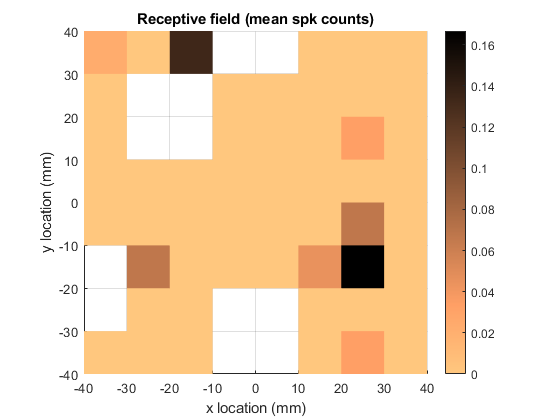

scnt = zeros(length(StimXloc),length(StimYloc));
for ii = 1:length(StimXloc) % loop through stimulus positions
    for jj = 1:length(StimYloc)
        validStimIndices = GaborPatchIndices.x_position == StimXloc(ii) & ...
            GaborPatchIndices.y_position == StimYloc(jj);
        StimConditionIds = unique(GaborPatchIndices.stimulus_condition_id(validStimIndices)); % matching stim conditions
        ValidConditionIds = ismember(spkCounts.stimulus_condition_id,StimConditionIds); % find stim conditions valid for unit
        scnt(ii,jj) = sum(spkCounts.spike_count(ValidConditionIds))/...
            sum(spkCounts.stimulus_presentation_count(ValidConditionIds));
    end
end
% plot the data
surf(StimXloc,StimYloc,scnt)
shading flat
axis square
view([0 90])
colorbar
ylabel('y location (mm)')
xlabel('x location (mm)')
title('Receptive field (mean spk counts)')

#### Determine the orientation tuning for this unit

Now that we have identified the unit's receptive field, we want to build an orientation tuning curve. For this, we need to first pick a time window in which the unit was responsive to determine its orientation tuning. To do this, we'll first pick the `"static_gratings"` [stimuli](http://observatory.brain-map.org/visualcoding/stimulus/static_gratings#:~:text=The%20static%20grating%20stimulus%20consists,the%20position%20of%20the%20grating).&text=At%20the%20intersections%20of%20these,corresponding%20to%20a%20different%20phase.). These were parallel bars of a range of orientations presented to the animal.

% Identify static grating stimuli
stimuli = sess.stimulus_presentations;
staticGratingIndices = stimuli(stimuli.stimulus_name == "static_gratings", :);
stimulusPresentationIds = staticGratingIndices.stimulus_presentation_id;

We can use the `getPresentationwiseSpikeCounts()` method to measure the unit responses to these stimuli. Each stimulus was presented for 250ms; we'll form a peri-stimulus time histogram (PSTH) of several unit responses from the same probe, to choose a selective time window for the response. The slider allows you to select the number of units used for computing the PSTH (default: 5). The more the number of units selected, the longer it will take to load all the data. 

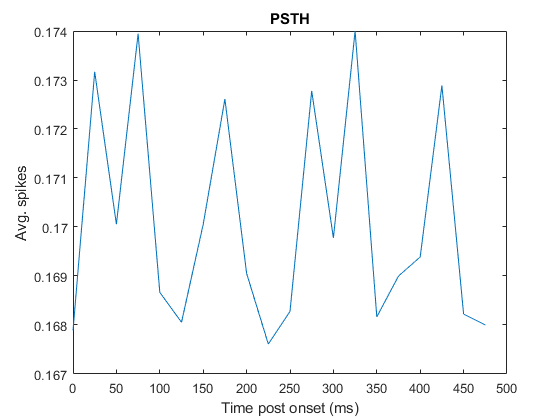

% Build a PSTH
nPsthUnits = 3;
timeBins = 0:25e-3:500e-3;
psth = sess.getPresentationwiseSpikeCounts(timeBins, stimulusPresentationIds, unit.probe.units{1:nPsthUnits, 'id'});
% Plot the PSTH
plot(timeBins(1:end-1) * 1e3, mean(psth, [2 3]));
xlabel('Time post onset (ms)');
ylabel('Avg. spikes');
title('PSTH');

The responsive period is around 50–200ms post stimulus onset. We can use the same BOT method `getPresentationwiseSpikeCounts()` to extract the responses to all oriented grating stimuli. We can then plot the response of the sinlge unit relative to the orientation of the stimulus presented to the animal.

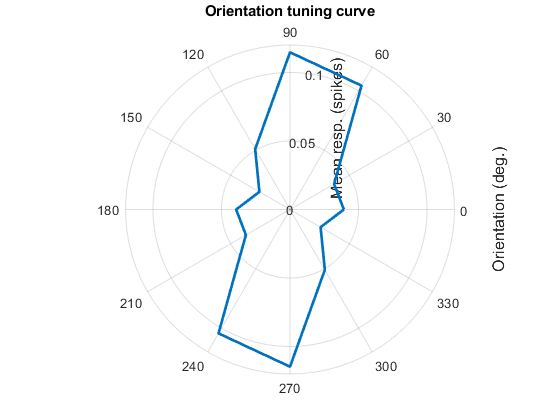

% Compute the individual stimulus responses
respWindow = [50 200] * 1e-3;
responses = sess.getPresentationwiseSpikeCounts(respWindow, stimulusPresentationIds, unit.id);
% Collect stimuli by stimulus orientation
stimOrientation = staticGratingIndices.orientation;
[condOrientation, ~, oriIndex] = unique(stimOrientation);
blanks = isnan(stimOrientation);
oriIndex(blanks) = 7;
% Calculate mean and std. dev. of responses per stimulus orientation
respMean = accumarray(oriIndex, responses, [], @mean);
respStd = accumarray(oriIndex, double(responses), [], @std);
% Plot an orientation tuning curve
orientation = deg2rad(condOrientation);
orientation = [orientation(1:6); orientation(1:6) + pi; orientation(1)];
polarplot(orientation, respMean([1:6 1:6 1]), 'LineWidth', 2);
a = gca;
a.RAxis.Label.String = 'Mean resp. (spikes)';
a.ThetaAxis.Label.String = 'Orientation (deg.)';
title('Orientation tuning curve')

As might be expected, this unit from primary visual cortex was tuned to the orientation of a visual stimulus.

## Accessing probe-centric data

Individual probes in the Neuropixels data set are associated with current-source density (CSD) and local-field potential (LFP) measurements. These are accessed using methods from `probe` objects.

Let's examine the CSD and LFP data associated with the probe corresponding to the unit we've been examining.

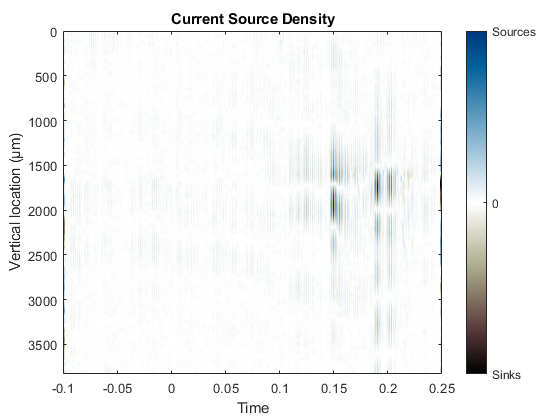

% Get the probe object for this unit
probe = unit.probe;

% Extract CSD data for this probe
tt = probe.csdData.data; % timetable 
vposns = probe.csdData.verticalPositions;

% Plot the CSD data
figure, imagesc(seconds(tt.Time), vposns, table2array(tt));
colormap(vertcat(flipud(1-bone()), 1-copper()));
max_amp = max(abs(caxis));
colorbar('Ticks',[-max_amp,0,max_amp],'Ticklabels',{'Sinks','0','Sources'})
caxis([-1 1] * max_amp);
xlabel('Time');
ylabel('Vertical location (µm)');
title('Current Source Density');

## Utility functions

function prepareForDemo
clearvars
warning('off')
clc
end

## References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[2] Copyright 2016 Allen Institute for Brain Science. Visual Coding – Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[3] Copyright 2017 Allen Institute for Brain Science. Technical White Paper on the Mouse Common Co-ordinate Framework. Available from: [http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2](http://help.brain-map.org/download/attachments/2818171/Mouse_Common_Coordinate_Framework.pdf?version=4&modificationDate=1508448259091&api=v2)

[4] Copyright 2016 Allen Institute for Brain Science. SDK documentation. Available from: [https://allensdk.readthedocs.io/en/latest/visual_coding_neuropixels.html](https://allensdk.readthedocs.io/en/latest/visual_coding_neuropixels.html)

[5] Copyright 2019 Allen Institute for Brain Science. Technical White Paper on the Neuropixels Dataset. Available from: [https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf](https://brainmapportal-live-4cc80a57cd6e400d854-f7fdcae.divio-media.net/filer_public/80/75/8075a100-ca64-429a-b39a-569121b612b2/neuropixels_visual_coding_-_white_paper_v10.pdf)